clc
clear
load("DataAndVariables\BaseDefinitions.mat")
measuremedOutputs = [Psch(2:end,:) ; Qsch(2:end,:)];
[Vout, Sout, Sensitivity, J] = NewRapV2(measuremedOutputs(:,1));

time = 9000;
t = linspace(0,10,time);
V(:,1) = Vout(15:end);
for i=2:time
    dV = J \ [normrnd(0,0.01,14,1);normrnd(0,0.01/5,14,1)];
    V(:,i) = V(:,i-1) + dV(15:end);
end

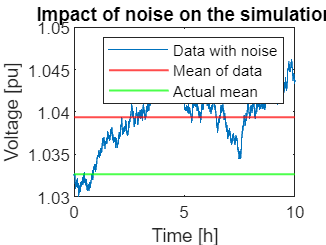

plot(t,V(5,:)')
yline(mean(V(5,:),2),LineWidth=1,Color=[1,0,0])
yline(Vout(19),LineWidth=1,Color=[0,1,0])
title("Impact of noise on the simulation") % using linearisation at each step
ylabel("Voltage [pu]")
xlabel("Time [h]")
legend("Data with noise", "Mean of data", "Actual mean")
% ylim([1.02,1.04])
set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
% saveas(gcf,'Figure/ImpactOfNoise','epsc')